# Calculating the derivative of a signal

There are three ? marks in the line 

## Dw=sum(?.*exp(-j*?*?))*t_step;

Change to the correct code and run the section

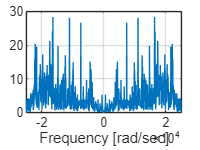


clear
load for_ps3.mat
t_step = t_vector(2) - t_vector(1);

% Länge des ft Vectors
L = length(ft_vector);

% Berechung der Ableitung von den Werten des ft_vectors
diff_ft = (ft_vector(2:L) - ft_vector(1:(L-1))) / t_step;

% Den Zeit vector (t_vector) an die Länge der Ableitung anpassen weil wir
% die Ableitung numerisch ausgerechnet haben zwischen zwei wert Paren fehlt
% hinten ein wert.
t_vector = t_vector(1:(L-1));

Dw_vector = [];
w_vector = [];

% wir lassen w von -25000 bis 25000 mit 50er schritten gehen.
for w = -25000:50:25000
    

    % Die Fourier Transformation für die Ableitung ausrechnen.
    % die Fehlenden Terme waren diff_ft, w und der neue t_vector. Die
    % Ableitung wird wie eine Art Fenster benutzt.
    Dw = sum(diff_ft .* exp(-j * w * t_vector)) * t_step;

    % Den Wert der Ableitung dem DW_Vector hinzufügen
    Dw_vector = [Dw_vector Dw];
    % w wert zum w vector hinzufügen.
    w_vector = [w_vector w];
end

% Plot
plot(w_vector, abs(Dw_vector));
xlabel('Frequency [rad/sec]');
grid on;